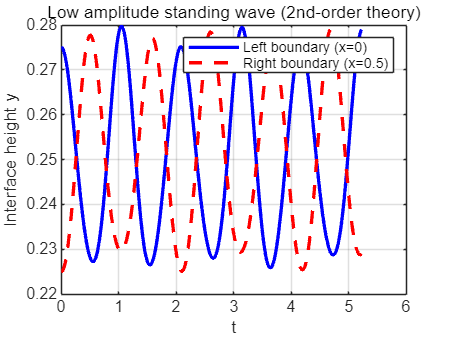

clc; clear; close all;

%% ================== 参数 ==================
A  = 0.025;        % 振幅
hs = 0.25;         % 静水深
g  = 2*pi;         % |g|
kn = 2*pi;         % 波数

% 频率（线性理论）
omega_n  = sqrt(g * kn * tanh(kn * hs));
omega_2n = sqrt(g * (2*kn) * tanh(2*kn * hs));

%% ================== 时间 ==================
T = 2*pi / omega_n;        % 周期
t = linspace(0, 5*T, 1000);

%% ================== 二阶系数 ==================
C0 = (1/8)*(omega_n^4 + g^2 * kn^2)/omega_n^4;

C1 = (1/8)*(3*omega_n^4 - g^2 * kn^2)/omega_n^4 ...
    - (3/2)*(omega_n^4 - g^2 * kn^2)/(omega_n^2*(4*omega_n^2 - omega_2n^2));

C2 = (1/2)*(omega_2n^2*omega_n^2 - omega_n^4 - 3*g^2*kn^2) ...
    /(omega_n^2*(4*omega_n^2 - omega_2n^2));

% 注意：二阶项系数（来自公式(14)）
coef = (A^2 * omega_n^2)/g;

%% ================== 左边界 x = 0 ==================
zL = A*cos(omega_n*t) ...
   + coef * ( ...
       C0 ...
     + C1*cos(2*omega_n*t) ...
     + C2*cos(omega_2n*t) ...
   );

yL = hs + zL;

%% ================== 右边界 x = 0.5 ==================
% cos(kn x) = -1, cos(2kn x)=1
zR = -A*cos(omega_n*t) ...
   + coef * ( ...
       C0 ...
     + C1*cos(2*omega_n*t) ...
     + C2*cos(omega_2n*t) ...
   );

yR = hs + zR;

%% ================== 作图 ==================
figure;
plot(t, yL, 'b-', 'LineWidth', 2); hold on;
plot(t, yR, 'r--', 'LineWidth', 2);
xlabel('t');
ylabel('Interface height y');
legend('Left boundary (x=0)', 'Right boundary (x=0.5)');
title('Low amplitude standing wave (2nd-order theory)');
grid on;


%% ================== 导出 txt ==================
data = [t(:), yL(:), yR(:)];   % 三列：t, yL, yR

writematrix(data, 'sloshing_data.txt', 'Delimiter', 'tab');